## **Heavy Frame**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D ./ 2;                        % Fuselage radius (m)
C = 2 * pi * r;                    % Fuselage circumference (m)

**0.3 Material Properties**

E_f = 67000000000;                 % Young's Modulus (N/m^2)
rho_f = 2860;                      % Density (kg/m^3)
sigma_y = 614000000;               % Tensile yield stress (Pa)
tau_y = sigma_y ./ sqrt(3);        % Shear yield stress (Pa)

pi * sqrt(E_f/sigma_y)

ans = 32.8173

**0.4 Critical Loading Conditions**

Q = -5.909040918344827e+03;        % Maximum shear force (N)
P = 3.595539750957855e+04;         % Maximum tangential load (N)
T = 8.496619985488507e+04;        % Maximum torque (Nm)

### **1 WISE curve**

**1.1 Find WISE curve**

% Define theta range (0 to 2*pi for full fuselage section)
theta = linspace(0, 2 * pi, 1000);

% Compute shear flow distributions for P, Q, and T load cases
M_P = -(P * r / (2 * pi)) .* ((3 * sin(theta) / 2) + (pi - theta) .* (cos(theta) - 1));
N_P = -(P / (2 * pi)) .* ((sin(theta) / 2) - (pi - theta) .* cos(theta));
S_P = -(P / (2 * pi)) .* (((pi - theta) .* sin(theta)) - 1 - (cos(theta) / 2));

M_Q = -(Q * r / (2 * pi)) .* ((cos(theta) / 2) - (pi - theta) .* sin(theta) + 1);
N_Q = -(Q / (2 * pi)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_Q = -(Q / (2 * pi)) .* (((pi - theta) .* cos(theta)) - (sin(theta) / 2));

M_T = -(T / (2 * pi)) .* (pi - 2 * sin(theta) - theta);
N_T = -(T / (2 * pi * r)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_T = -(T / (2 * pi * r)) .* (1 + 2 * cos(theta));

% Compute total shear flow distributions
M_total = M_P + M_Q + M_T;
N_total = N_P + N_Q + N_T;
S_total = S_P + S_Q + S_T;

1.2 Plotting the result

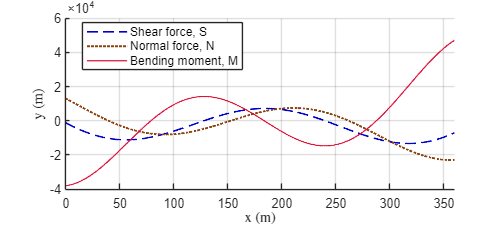

figure(1)

clf;

hold on;

plot(theta * 180 / pi, S_total, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(theta * 180 / pi, N_total, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5);
plot(theta * 180 / pi, M_total, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.);

% Legends
legend("Shear force, S", "Normal force, N", "Bending moment, M", "Location", "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('x (m)', 'Interpreter', 'latex');
ylabel('y (m)', 'Interpreter', 'latex');

% Set plot limits and grid
xlim([0 360]);
grid on;

hold off;

% Set figure size
set(gcf, 'Position', [0 0 500 225]);

1.3 Find the maximum

S_max = max(abs(S_total))

S_max = 1.3282e+04

N_max = max(abs(N_total))

N_max = 2.2980e+04

M_max = max(abs(M_total))

M_max = 4.6983e+04

M_min = min(M_total)

M_min = -3.7983e+04

### **2 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**2.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass_hf(x(1), x(2), x(3), x(4));            % (t_web, t_fl, b_f, h_f)

Define initial point for the objective function

x0 = [10 / 1000, 10 / 1000, 50 / 1000, 100 / 1000];   % take average from literiture review

Boundary conditions

lb = [1 / 1000, 1 / 1000, 10 / 1000, 10 / 1000];       % change dynamically
ub = [0.05, 0.05, 0.5, 0.5];                           % change dynamically

Nonlinear constraints

nonlcon = @Non_linear_hf_6;

**2.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch('NumTrialPoints', 2000, 'MaxWaitCycle', 100);

**2.2 Run optimisation**

[x_opt, f_opt] = fmincon(fun, x0, [], [], [], [], lb, ub, nonlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.0071    0.0102    0.0730    0.0897


f_opt = 121.9021

[x_opt, f_opt] = run(gs, problem);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.146480e+02    8.899e+07    1.570e+03
    1      10    1.145180e+02    7.904e+07    1.556e+03    2.579e-03
    2      15    1.144912e+02    7.803e+07    1.550e+03    2.303e-04
    3      20    1.152188e+02    7.077e+07    1.429e+03    4.426e-03
    4      25    1.166809e+02    6.517e+07    1.358e+03    4.465e-03
    5      30    1.243153e+02    4.932e+07    1.944e+03    1.686e-02
    6      35    1.243508e+02    4.920e+07    1.949e+03    5.877e-05
    7      40    1.235411e+02    4.577e+07    1.972e+03    9.540e-04
    8      45    1.181034e+02    2.713e+07    2.072e+03    6.030e-03
    9      50    1.180890e+02    2.700e+07    2.073e+03    2.924e-05
   10      55    1.180889e+02    2.700e+07    2.073e+03    2.474e-07
   11      60    1.180889e+02    2.700e+07    2.073e+03    6.143e-08
   12      65    1.222782e+02    1.045e+06    2

   49     273    1.219636e+02    2.736e+02    9.178e-01    1.550e-04


   50     279    1.219202e+02    8.409e+02    6.279e-01    8.709e-05


   51     285    1.218926e+02    4.468e+02    6.279e-01    5.149e-05


   52     290    1.218426e+02    5.152e+02    6.279e-01    9.010e-05


   53     295    1.218383e+02    7.719e+02    6.279e-01    5.056e-06
   54     300    1.218383e+02    5.097e+02    6.279e-01    2.809e-07


   55     305    1.218381e+02    7.655e+02    6.279e-01    1.704e-07


   56     310    1.218381e+02    5.048e+02    6.279e-01    2.576e-07


   57     315    1.218379e+02    7.591e+02    6.279e-01    1.688e-07


   58     320    1.218379e+02    4.999e+02    6.279e-01    2.555e-07


   59     325    1.218377e+02    7.527e+02    6.279e-01    1.672e-07


   60     330    1.218377e+02    4.950e+02    6.279e-01    2.534e-07



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
   61     335    1.218375e+02    7.464e+02    6.279e-01    1.656e-07


   62     340    1.218375e+02    4.902e+02    6.279e-01    2.513e-07


   63     345    1.218373e+02    7.401e+02    6.279e-01    1.640e-07


   64     350    1.218373e+02    4.854e+02    6.279e-01    2.493e-07


   65     355    1.218371e+02    7.339e+02    6.279e-01    1.625e-07



Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.

                                            First-order      Norm of
 Iter F-count    

### **3 Validate Result**

**3.1 Assign x values**

t_web = x_opt(1); % web thickness (m)
t_web * 1000      % 15-25 mm

ans = 7.1283

t_fl = x_opt(2);  % flange thickness (m)
t_fl * 1000       % 25-40 mm

ans = 10.1929


b_f = x_opt(3);   % frame width (m)
b_f * 1000        % 200-400 mm

ans = 72.9632

h_f = x_opt(4);   % frame height (m)
h_f * 1000        % 300-500 mm

ans = 89.6614

**2.2 Calculate mass**

% Find second moment of inertia
[I_x, A] = I_hf(t_web, t_fl, b_f, h_f);
I_x * 1000 ^ 4

ans = 3.4304e+06


A * 1000 ^ 2

ans = 2.1265e+03


% Calcualte frame mass
m_f = rho_f * A * C

m_f = 121.9021

**2.3 Calculate constraint**

% Slenderness ratio
1.2 * sqrt(E_f/sigma_y)

ans = 12.5353

(h_f / t_web) - 1.2 * sqrt(E_f/sigma_y)

ans = 0.0429

h_f / t_web

ans = 12.5782

0.7 * sqrt(E_f/sigma_y)

ans = 7.3123

(b_f / t_fl) - 0.7 * sqrt(E_f/sigma_y)

ans = -0.1540

b_f / t_fl

ans = 7.1583


%
% Maximum direct stress
N_max / A - sigma_y

ans = -6.0319e+08

(sigma_y)  / 1e6

ans = 614

(N_max / A)  / 1e6

ans = 10.8061


%
% Maximum shear stress
Q_x = b_f * t_fl * (h_f/2 - t_fl/2);
(S_max * Q_x) / (I_x * t_web) - tau_y

ans = -3.3844e+08

tau_y  / 1e6

ans = 354.4931

((S_max * Q_x) / (I_x * t_web)) / 1e6

ans = 16.0509


%
% Maximum bending stress
(M_max * h_f) / (2 * I_x) - sigma_y

ans = 0.4903

sigma_y / 1e6

ans = 614

((M_max * h_f) / (2 * I_x)) / 1e6

ans = 614.0000

((M_min * h_f) / (2 * I_x)) / 1e6

ans = -496.3816

### **4 Buckling analysis**

% From ESDU datasheet 
% (see Structure 3 Lecture Notes for k to K calculation)
Kc = 3.69; % 3.62 for v = 0.3
Ks = 4.93; % 4.83 for v = 0.3
% Flange Local Buckling:
BCf = Kc * E_f * ((t_fl / b_f) ^ 2);
BCf / 1e6

ans = 4.8249e+03

% Web Shear Buckling:
BCw = Ks * E_f * ((t_web / h_f) ^ 2);
BCw / 1e6

ans = 2.0878e+03

% Web compressive Buckling:
BCw2 = Kc * E_f * ((t_web / h_f) ^ 2);
BCw2 / 1e6

ans = 1.5627e+03